function [BW,maskedImage] = segmentPuzzle34(X)
%segmentImage Segment image using auto-generated code from imageSegmenter app
%  [BW,MASKEDIMAGE] = segmentImage(X) segments image X using auto-generated
%  code from the imageSegmenter app. The final segmentation is returned in
%  BW, and a masked image is returned in MASKEDIMAGE.

% Auto-generated by imageSegmenter app on 29-Aug-1997
%----------------------------------------------------

X = im2gray(X); 

% Adjust data to span data range.
X = imadjust(X);

% Threshold image - adaptive threshold
BW = imbinarize(X, 'adaptive', 'Sensitivity', 0.500000, 'ForegroundPolarity', 'bright');

% Erode mask with disk
radius = 2;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imerode(BW, se);
% BW = bwpropfilt(BW,"Area",[300,inf]);

% Dilate mask with disk
radius = 4; 
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imdilate(BW, se);

% Clear borders
BW = imclearborder(BW);

% Fill holes
BW = imfill(BW, 'holes');

% Create masked image.
maskedImage = X;
maskedImage(~BW) = 0;
end

function [BW_out,properties] = filterRegions(BW_in)
%filterRegions Filter BW image using auto-generated code from imageRegionAnalyzer app.

% Auto-generated by imageRegionAnalyzer app on 21-May-2025
%---------------------------------------------------------

BW_out = BW_in;

% Filter image based on image properties.
BW_out = bwpropfilt(BW_out,'Area',[22000, 24512]);

% Get properties.
properties = regionprops("table",BW_out, {'Area', 'Eccentricity'});
end

puzzleImage = imread("Puzzle_34.jpg");
puzzleMask = segmentPuzzle34(puzzleImage);

[threePieceMask, threePieceProperties] = filterRegions(puzzleMask);
threePieceProperties

threePieceProperties = 4×1 struct array with fields:
    Area
    Eccentricity


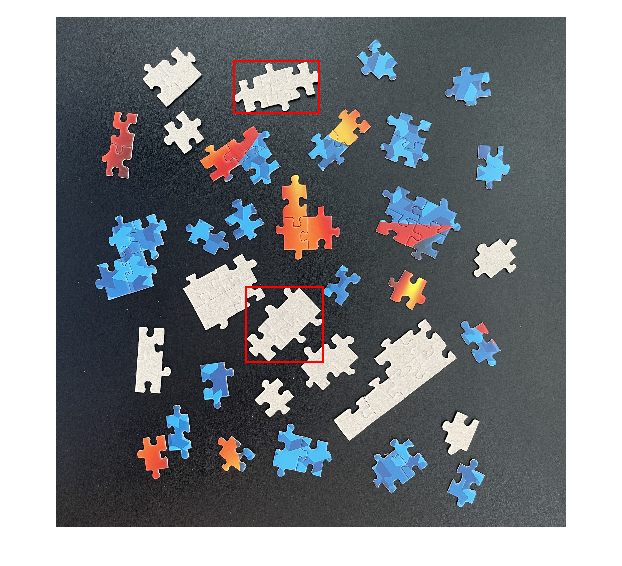


eccentricities = [threePieceProperties.Eccentricity];
N = sum(eccentricities > 0.8);

threePieceMaskLinear = bwpropfilt(threePieceMask, "Eccentricity", N);
threePieceLinearBoxes = regionprops("table",threePieceMaskLinear, "BoundingBox");

puzzleImageBoxed = insertShape(puzzleImage,"Rectangle",threePieceLinearBoxes.BoundingBox,"color","red","LineWidth",5); 
figure, imshow(puzzleImageBoxed);

N = 2